# Thermoeconomic Diagnosis Demo

Use ThermoeconomicDiagnosis function to compare two states of the plant and to make diagnosis

#### Select and read the data model file

file="D:\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.StateNames);
State=convertStringsToChars(States(4));
DiagnosisMethod='WASTE_INTERNAL';

#### Compute Diagnosis Analysis

res=ThermoeconomicDiagnosis(data,'State',State,'DiagnosisMethod',DiagnosisMethod,'Show',true);

Fuel Impact:          3.5000 (kW)
Malfunction Cost:     3.5000 (kW)


Diagnosis Summary - PCND2

Key        MF(kW)      ΔI(kW)      ΔR(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPt*(kW)
——————————————————————————————————————————————————————————————————————————————————————————
BLR       -0.7305      0.3400      3.2440      0.0000     -0.7305      4.4733      0.0000
TRB       -0.0838     -0.0570      0.0000      0.0000     -0.0489     -0.0104      0.0000
IHE       -0.1149     -0.0390      0.0000      0.0000     -0.1548     -0.0328      0.0000
PMP       -0.0039      0.0120      0.0000      0.0000     -0.0066     -0.0014      0.0000
CND        0.0000      0.0000      0.0000      0.0000      0.0100      0.0021      0.0000
ENV       -0.9331      0.2560      3.2440      0.0000     -0.9309      4.4309      0.0000


Malfunction Table (kW) - PCND2

 key             BLR        TRB        IHE        PMP        CND        ΔPs
————————————————————————————————————————————————————————————————————————

#### Show Graph Results

Show Default graph (Malfuncion Cost Table)

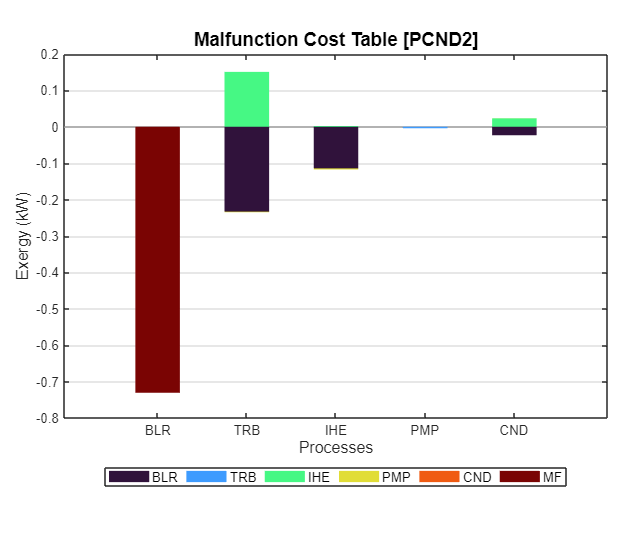

ShowGraph(res,'ShowOutput',false);

Show Total Malfunction Cost Graph

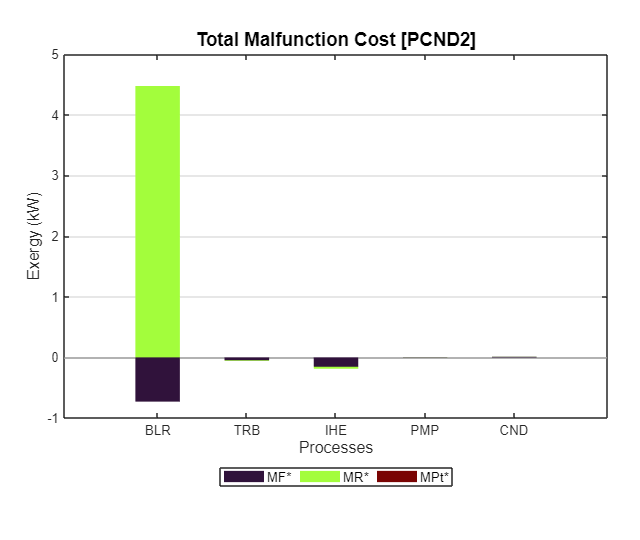

ShowGraph(res,'Graph','tmfc');

Show Fuel Impact graph

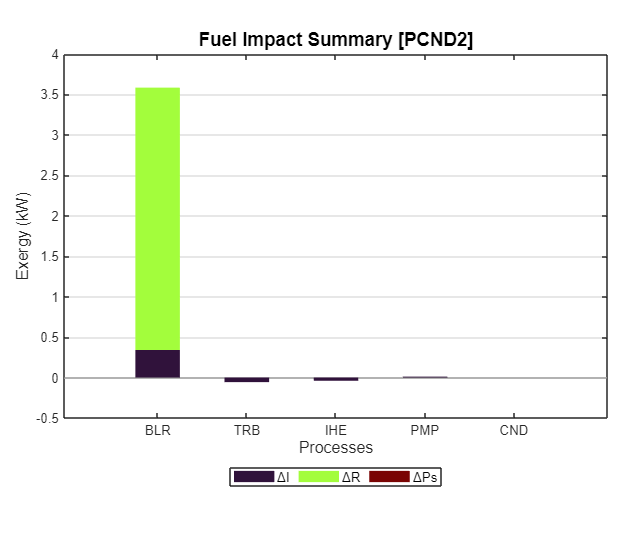

ShowGraph(res,'Graph','dft');

#### Additional Help

help ThermoeconomicDiagnosis

 ThermoeconomicDiagnosis - Compare to states of the plant and make a thermoeconomic diagnosis
    This function makes a thermoeconomic diagnosis of the plant, comparing two plant states. 
    Two different methods could be used to analyze the increase in waste generation: 
    'WASTE_EXTERNAL' accounts for the increase in the cost of waste, and
    'WASTE_INTERNAL' internalises the waste cost to the productive processes that generate them. 
    The data model must have at least two states defined to perform the analysis.
  
  Syntax
 	res = ThermoeconomicDiagnosis(data,Name,Value)
  
  Input Arguments
    data - cReadModel object containing the data information
     
  Name-Value Arguments
    Reference State - Reference State. If not provided first state is used
      char array
    State - State to compare. If not provided second state is used
      char array
    DiagnosisMethod - Select the method to compute diagnosis
      'WASTE_EXTERNAL' Waste a